# ECSE 343: Numerical Methods for Engineers- Assignment 1- part a

Due Date:  21st Feb. 2023

Student Name: Simon Li

Student ID:    260984998

## Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

## Please submit this **.mlx** file along with the **PDF** copy of this file.

## **Question 1:  Fixed Point Number Repersentation (10 marks)**

One possible way to store represent numbers in computer is to use **fixed **point integer method. Suppose we have a 64-bit fixed point integer representation, where we use 31bits for the integer part and 32 bits for the fraction part and 1 bit is reserved for the the sign bit. The visual representation of our number is shown below, 

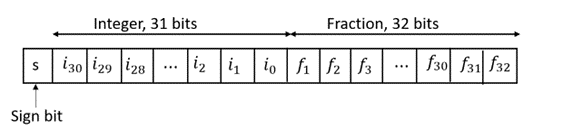

Using the above scheme any number can be represented as following


$$i_{30} 2^{30} +\ i_{29} 2^{29} +\ldots+\ i_1 2^1 +i_2 2^0 +f_1 2^{-1} +f_2 2^{-2} +\ldots+f_{31} 2^{-31} +f_{32} 2^{-32}$$


For example, 43.625  can be represented as,

Where, 0 is used to represent the positive sign and  0000...0000101011 is a 31 bit binary value for decimal 43 and 1010000...0000 is a 32 bit binary value for fractional 0.625.

    a) Find the smallest and the largest positive number that can be represented in this format.

    *% large: 2^31-2^-32, small: 2^-32*

    b) Give an upper bound on the *absolute *error due to rounding on numbers stored using the above **64-bit fixed point** representation.

*    % 2^-1*

    c) Give an upper bound on the *relative *error due to rounding on numbers stored using the above **64-bit fixed point** representation.

    *% 100%*

    d) Find the largest and smallest positive numbers that can be represented as a **64-bit****floating** **point **number? 

        *% type your answer here*

## Question 2:  Round off errors **(10 marks)**

    a)  The MATLAB function `eps(x) `provides difference between x and the next higher number that can be stored using floating point representation on a computer. 

 Use the MATLAB function `eps`(x) to compute the value of $ $\epsilon $$  for different values of n. Use x = 1,2,3,4,5,…,1000.  Plot $ $\epsilon $$  vs *x *, explain the results obtained.

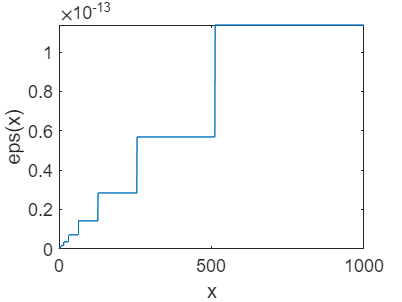

% write your code here 
x = [1:1000];
plot(x, eps(x));
xlabel('x');
ylabel("eps(x)");

    b) Write your own function named *myeps(x)* to compute difference between x and the next higher number. Your function should take integer x as input and provide the  difference between x and the next higher number that can be stored in 64 bit floting point  reprsentation. Write your function in the appendix of this mlx file and test it in the cell below.

Test your function for  x = 1,2,3,4,5,…,1000. Plot the output of your function vs x, explain the results obtained.

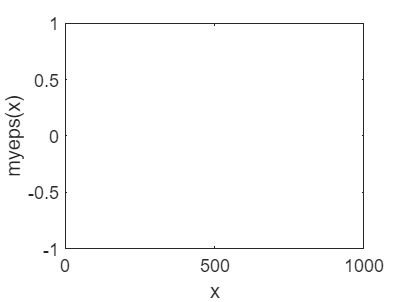

% write your code here 
x = [1:1000];
plot(x, myeps(x));
xlabel('x');
ylabel("myeps(x)");

*% type your answer here*

` c) `The relative error due to rounding is defined as,

                                                            
$$\eta_x = \left| \frac{x - \hat{x}} {x} \right |$$


    where x is the actual value and $\hat{x}$ is the value stored as a  floating point number. Write a function to estimate the value of the relative error as a  function of the stored value, you may use the MATLAB function provided in part (a). 

Use $\hat{x}$ = 1,2,3,4,5,…,1000.  Plot $\eta_x$vs $\hat{x}$, explain the results obtained using your function.  Is there an upper bound for it?  If so what is it? 

% write your code here

*% type your answer here*

d) The MATALB function call `eps(‘single’)` computes the machine epsilon for single precision (32bit) floating point numbers.

  Using your knowledge of the floating-point representation find an expression that computes the output of that funciton.

*% type your answer here*

## Question 3:  Numerical Derivatives **(10 marks)**

The derivative of a function, f(x), can be computed using the finite difference method, which can be derived using the first-order terms of the Taylor series expansion of the function, about : 

$f{\left(x_0 +h\right)}=f{\left(x_0 \right)}+hf^{\prime } {\left(x_0 \right)}+\frac{1}{2!}f^{\prime \prime } {\left(x_0 \right)}h^2 +\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}h^3 +\ldots$                    (2.1)

Rearranging terms to solve for $f^{\prime } {\left(x_0 \right)}$  and ignoring (truncating) the higher-order terms, we obtain the first order approximation of derivative

$f^{\prime } {\left(x_0 \right)}\;\approx \frac{f{\left(x_0 +h\right)}-f{\left(x_0 \right)}}{h}$                              (2.2)

    In this part, we will implement the code to compute the derivative of tan(x) at $x_{0\;} =\frac{\pi }{4}$ using the divided differences formula shown in equation (2.2).  

    a) Assuming that $h << 1$, find an expression for an estimate of the truncation error in eq. (2.2)?

        *% type your answer here*

    b) Use the cell below to implement the numerical derivative of  tan(x) using (2.2). Compute the numerical derivative $f'(x_0)$   for 100 logarthimically spaced values of *h *between ${10}^{-20\;}$ to ${10}^0$.  Also, evaluate the expression for truncation error obtained in part a) for different values of h. 

Compute the absolute error  between the analytical value of derivative and the estimated value of the derivative obtained using equation (2.2).

Plot the absolute error and the truncation error vs h on the same plot.  Explain the behavior of error as function of h as shown on the plot.

% write your code here 
h = logspace(-20,1,100);  % logarithmically spaced values of h

total_absErr % total absolute error. You need to compute it. It is the difference between analytical sol.
             % and numerical approx.

clf
figure(1)
loglog(h,total_absErr,'b','linewidth',2,'displayname','Total Error')
hold on
loglog(h(25:100),truncation_error(25:100),'r:','linewidth',2,'displayname','Truncation Error')
xlabel('Step size, h')
ylabel('Error in derivative of f(x)')
grid on
legend

        *% type your answer here*

     c) In  part (b), at which value of h did you obtain the minimum error. Justify your answer and show all the computations.

*% type your answer here*

d) Another way to compute the derivative is to use the* Central Difference method*.    Writing the Taylor series expansion of $f\left(x_0 -h\right)$ around $x_0$, we get 

$\left.{\left(x_0 -h\right)}=f{\left(x_0 \right)}+f^{\prime } {\left(x_0 \right)}\ \left(-h\right)+\frac{1}{2!}f^{\prime \prime } {\left(x_0 \right)}h^2 +\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}{\left(-h\right.}^3 \right)+\ldots$          (2.3)

Subtracting (2.3) from (2.1),  and ignoring the higher-order terms, we get

$f^{\prime } {\left(x_0 \right)}\approx \frac{f{\left(x_0 +h\right)}-f{\left(x_0 -h\right)}}{2h}-\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}{\ h}^2 -\frac{1}{4!}f^{\prime \prime \prime \prime } {\left(x_0 \right)}{\ h}^3 +\ldots$           (2.4)

Truncating the higher order terms, we get the expression for *Central Difference *approximation for the derivative as, 

$f^{\prime } {\left(x_0 \right)}\approx \frac{f{\left(x_0 +h\right)}-f{\left(x_0 -h\right)}}{2h}$                              (2.5)

What is the expression for truncation error? 

Use the cell below to compute the derivative of tan(x) at $x_0 =\frac{\pi }{4}$using the divided  differences formula shown in equation (2.5). You may use the code provided for part b) as a starting point. 

Include plot of  the absolute error and the truncation error vs h in your report.  

% write your code here


*% type your answer here*

e) Similar to part c). find the optimal value of  h where you obtain the minimum error. Justify your answer and show all the work.

*% type your answer here*

f) Which difference formula gives a smaller absolute error?  Explain.

*% type your answer here*

## Question 4: Solving systems of equations. **(20 marks)**

    a) Write a function named *LU_decomposition.m * in the Appendix of this file to compute the LU factorization using Gaussian Elimination. 

    b) Write a function named *LU_rowpivot.m *to compute the Gaussian Elimination based LU factorization **using the partial pivoting** (row pivoting,). Choose the elements with maximum magnitude as pivots. The function should take matrix  as the input and should output L, U and P matrices. Write your function in the Appendix of this file.

    c)  Write the  functions named *forward_sub.m *and* backward_sub.m*  to compute the forward and backward substitutions, respectively. Add  your functions in the appendix of this file.

    d)  In the cell below use the LU decomposition implemented in part (a) along with forward and backward substitution functions written in part (c) to solve the following system of equations. List the values of vector X obtained.  


$$\underset{A}{\underbrace{{\left[\begin{array}{cccc}
1e-16 & 50 & 5 & 9\\
0.2 & 5 & 7.4 & 5\\
0.5 & 4 & 8.5 & 32\\
0.89 & 8 & 11 & 92
\end{array}\right]}} } \underset{X}{\underbrace{{\left[\begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right]}} } =\ \underset{b}{\underbrace{{\left[\begin{array}{c}
40\\
52\\
18\\
95
\end{array}\right]}} }$$


    e) In the cell below use the LU decomposition with partial pivoting implemented in part (b) along with forward and backward substitution functions written in part (c) to solve the above system of equations. List the values of vector X obtained.  

   f) Comment on solutions obtained in part (d) and (e). Use the residual to determine which solution is more accurarte.

*        % type your answer here*

## Appendix

Write your functions here.

## Write code for Question 2 here

function y = myeps(x)
    % Define the machine epsilon for a 64-bit floating-point representation
    epsilon = 2^-52;
    
    % Initialize the output value
    y = epsilon;
    
    % Keep doubling the value of epsilon until x + epsilon is not equal to x
    while (x + y ~= x)
        y = y * 2;
    end
end


## Write code for Question 3 here

function [L, U] = LU_decompositon(A)
% L  is lower triagular matrix
% U is upper triangular matrix 
% YOUR CODE GOES HERE
end


function [L, U, P] = LU_rowpivot(A)
% L  is lower triagular matrix
% U is upper triangular matrix 
% P is the permutation matrix
% P*A = L*U
% YOUR CODE GOES HERE
end

function y = forward_sub(L,b)
% y is the vector
% L is the lower triangular matrix
%    YOUR CODE GOES HERE
end 

function X = backward_sub(U,y)
% X is the vector
% U is the upper triangular matrix
%    WRITE YOUR CODE HERE
end 



